# Track Lead Vehicle Position

This is taken from an existing Matlab example and modified to meet the needs of HW3.

## Overview

Automated Driving System Toolbox™ provides pretrained vehicle detectors and a multi-object tracker to facilitate tracking vehicles around ego car. The vehicle detectors are based on ACF features and Faster R-CNN, a deep-learning-based object detection technique. The detectors can be easily interchanged to see their effect on vehicle tracking.

The tracking workflow consists of the following steps:

- Define camera intrinsics and camera mounting position.

- Load and configure a pretrained vehicle detector.

- Set up a multi-object tracker.

- Run the detector for each video frame.

- Update the tracker with detection results.

- Display the tracking results in a video.

## Configure Vehicle Detector and Multi-Object Tracker

In this example, you use a pretrained ACF vehicle detector and configure this detector to incorporate camera information. By default, the detector scans the entire image at multiple scales. By knowing the camera parameters, you can configure the detector to detect vehicles on the ground plane only at reasonable scales.

% Configure the monoCamera object that contains the camera information.
% (values obtained by running devkit script on calibration files from KITTI
% dataset)
focalLength = [721.5377 721.5377];
principalPoint = [609.5593, 172.854];
% imageSize = [512 1382]; % Should be set based on the video - these values are for KITTI dataset videos
imageSize = [375, 1242]; % Should be set based on the video - these values are for KITTI dataset videos
% imageSize = [480 640]; % Should be set based on the video - these values are for matlab example video

intrinsics = cameraIntrinsics(focalLength,principalPoint,imageSize);
height = 1.65;
sensor = monoCamera(intrinsics,height);
% Do we need to set the Pitch as well?
% pitch = 14;
% sensor = monoCamera(intrinsics,height,'Pitch',pitch);

det_mat = load('detector.mat', 'detector');
detector = det_mat.detector;

%% PART 1
% Load the monoCamera object that contains the camera information.
% d = load('FCWDemoMonoCameraSensor.mat', 'sensor');
% sensor = d.sensor;
% 
% % Load a pretrained ACF vehicle detector. The ACF detector uses "Aggregate
% % Channel Features", which is fast to compute in practice. The 'full-view'
% % model is trained on images of the front, rear, left, and right side of
% % vehicles.
% detector = vehicleDetectorACF('full-view');


To try the Faster R-CNN vehicle detector, use [`vehicleDetectorFasterRCNN`](docid:driving_ref#bvkk0xo-1) instead. This detector requires a Deep Learning Toolbox™ license.

Configure the detector using the sensor information. The detector only tries to find vehicles at image regions above the ground plane. This can reduce computation and prevent spurious detections.

% The width of common vehicles is between 1.5 to 2.5 meters. Only a
% bounding box of width within this range is considered as a detection
% candidate in image.
vehicleWidth = [1.5, 2.5];

% Configure the detector using the monoCamera sensor and desired width.
detector = configureDetectorMonoCamera(detector, sensor, vehicleWidth);

% Initialize an multi-object tracker including setting the filter,
% the detection-to-track assignment threshold, the coasting and
% confirmation parameters. You can find the |setupTracker| function at the
% end of this example.
[tracker, positionSelector] = setupTracker();

## Track Vehicles in a Video

At each time step, run the detector, update the tracker with detection results, and display the tracking results in a video.

% Setup Video Reader and Player
% videoFile   = '/usr/local/MATLAB/R2018b/toolbox/driving/drivingdata/05_highway_lanechange_25s.mp4';
% videoReader = VideoReader(videoFile);
videoPlayer = vision.DeployableVideoPlayer();

% Replace this variable with the location of the MOSEG training images
imgDir = 'KITTI_MOD_fixed/testing/images';

% Replace this variable with the sequence you want to evaluate on
imgPattern = fullfile(imgDir, "2011_09_26_drive_0005_sync*png");

% Get all files in directory that match pattern
imgFiles = dir(imgPattern);

frame_count = length(imgFiles);

snapshot = [];
snapTimeStamp = 120;
% cont = hasFrame(videoReader);
leadVehicles = cell(500, 1);

for currentStep = 1:frame_count
    % Get full image path
    imgFname = fullfile(imgDir, imgFiles(currentStep).name);
        
    % Load image data
    frame = imread(imgFname);
    
    % Run the detector and package the returned results into an object
    % required by multiObjectTracker.  You can find the |detectObjects|
    % function at the end of this example.
    detections = detectObjects(detector, frame, currentStep);
       
    % Using the list of objectDetections, return the tracks, updated for
    % 'currentStep' time.
    confirmedTracks = updateTracks(tracker, detections, currentStep);
    
    % Remove the tracks for vehicles that are far away.
    confirmedTracks = removeNoisyTracks(confirmedTracks, positionSelector, sensor.Intrinsics.ImageSize);
    
    bboxes = getTrackPositions(confirmedTracks, positionSelector);
    xyVehicles = calculateXYLabels(confirmedTracks, bboxes,  sensor);
    leadVehicles{currentStep} = xyVehicles;
    
    % Insert tracking annotations.
    frameWithAnnotations = insertTrackBoxes(frame, confirmedTracks, bboxes, xyVehicles);

    % Display the annotated frame.    
    videoPlayer(frameWithAnnotations);  
    
    % Take snapshot for publishing at snapTimeStamp seconds
    if currentStep == snapTimeStamp
        snapshot = frameWithAnnotations;
    end   
%     
%     % Exit the loop if the video player figure is closed by user.
%     cont = hasFrame(videoReader) && isOpen(videoPlayer);
end

Frame 1.000000 has width greater than 1242.000000, width value = 382.126594 
Frame 1.000000 has width greater than 1242.000000, width value = 384.779350 
Frame 1.000000 has width greater than 1242.000000, width value = 387.432105 
Frame 1.000000 has width greater than 1242.000000, width value = 390.084861 
Frame 3.000000 has width greater than 1242.000000, width value = 384.475592 
Frame 3.000000 has width greater than 1242.000000, width value = 387.610839 
Frame 3.000000 has width greater than 1242.000000, width value = 390.746087 
Frame 3.000000 has width greater than 1242.000000, width value = 393.881335 
Frame 3.000000 has width greater than 1242.000000, width value = 397.016582 
Frame 7.000000 has width greater than 1242.000000, width value = 376.912244 
Frame 7.000000 has width greater than 1242.000000, width value = 381.056167 
Frame 7.000000 has width greater than 1242.000000, width value = 382.822008 
Frame 3.000000 has width greater than 1242.000000, width value = 375.933859 

% The below code does not seem to work for mlx files!
% [currentFolder,fileName,fileExt] = fileparts(mfilename('fullpath'))
currentFolder = '/home/pkadubandi/GH/PradeepKadubandi/USC-CourseWork/599-CPS/HW3';
save(fullfile(currentFolder, 'AllLeadVehicles.mat'), 'leadVehicles');

Show the tracked vehicles and display the distance to the ego car. 

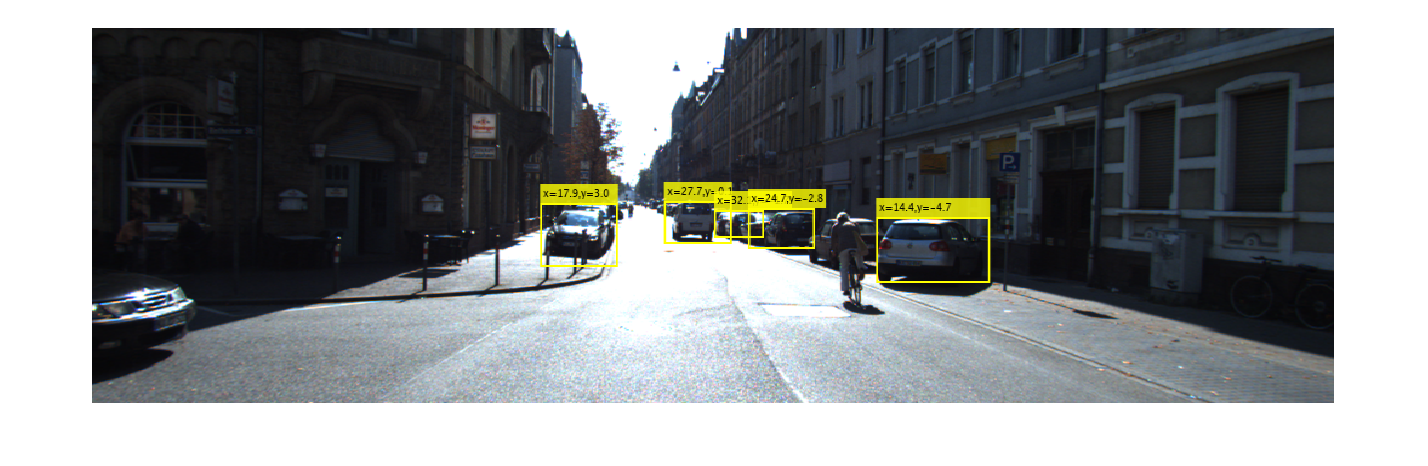

if ~isempty(snapshot)
    figure
    imshow(snapshot)
end

The tracking workflow presented here can be easily integrated into the [Visual Perception Using Monocular Camera](docid:driving_examples.mw_b13b3ce9-9de9-4d94-a014-13a01f2ca568) example, where the vehicle detection step can be enhanced with the tracker. To learn about additional tracking capabilities in Automated Driving System Toolbox™, see [`monoCamera`](docid:driving_ref#bvgu10o-1) and [`multiObjectTracker`](docid:driving_ref#bvigrmf-1).

## Supporting Functions

**setupTracker** function creates a `multiObjectTracker` to track multiple objects with Kalman filters. When creating a `multiObjectTracker` consider the following:

- `FilterInitializationFcn`: The likely motion and measurement models. In this case, the objects are expected to have a constant velocity motion. See the 'Define a Kalman filter' section.

- `AssignmentThreshold`: How far detections can fall from tracks. The default value for this parameter is 30. If there are detections that are not assigned to tracks, but should be, increase this value. If there are detections that get assigned to tracks that are too far, decrease this value. This example uses 50.

- `NumCoastingUpdates`: How many times a track is coasted before deletion. Coasting is a term used for updating the track without an assigned detection (predicting). The default value for this parameter is 5. 

- `ConfirmationParameters`: The parameters for confirming a track. A new track is initialized with every unassigned detection. Some of these detections might be false, so all the tracks are initialized as  `Tentative`. To confirm a track, it has to be detected at least *M* times in *N* tracker updates. The choice of *M* and *N* depends on the visibility of the objects. This example uses the default of 3 detections out of 5 updates.

The outputs of `setupTracker` are:

- `tracker` - The `multiObjectTracker` that is configured for this case.

- `positionSelector` - A matrix that specifies which elements of the State vector are the position: `position = positionSelector * State`

function [tracker, positionSelector] = setupTracker()
    % Create the tracker object.
    tracker = multiObjectTracker('FilterInitializationFcn', @initBboxFilter, ...
        'AssignmentThreshold', 50, ...
        'NumCoastingUpdates', 5, ... 
        'ConfirmationParameters', [3 5]);

    % The State vector is: [x; vx; y; vy; w; vw; h; vh]
    % [x;y;w;h] = positionSelector * State
    positionSelector = [1 0 0 0 0 0 0 0; ...
                        0 0 1 0 0 0 0 0; ...
                        0 0 0 0 1 0 0 0; ...
                        0 0 0 0 0 0 1 0]; 
end

**initBboxFilter** function defines a Kalman filter to filter bounding box measurement.

function filter = initBboxFilter(Detection)
% Step 1: Define the motion model and state.
%   Use a constant velocity model for a bounding box on the image.
%   The state is [x; vx; y; vy; w; wv; h; hv]
%   The state transition matrix is: 
%       [1 dt 0  0 0  0 0  0;
%        0  1 0  0 0  0 0  0; 
%        0  0 1 dt 0  0 0  0; 
%        0  0 0  1 0  0 0  0; 
%        0  0 0  0 1 dt 0  0; 
%        0  0 0  0 0  1 0  0;
%        0  0 0  0 0  0 1 dt; 
%        0  0 0  0 0  0 0  1]
%   Assume dt = 1. This example does not consider time-variant transition
%   model for linear Kalman filter.
    dt = 1;
    cvel =[1 dt; 0 1];
    A = blkdiag(cvel, cvel, cvel, cvel);
 
% Step 2: Define the process noise. 
%   The process noise represents the parts of the process that the model
%   does not take into account. For example, in a constant velocity model,
%   the acceleration is neglected.
    G1d = [dt^2/2; dt];
    Q1d = G1d*G1d';
    Q = blkdiag(Q1d, Q1d, Q1d, Q1d);
 
% Step 3: Define the measurement model.
%   Only the position ([x;y;w;h]) is measured.
%   The measurement model is
    H = [1 0 0 0 0 0 0 0; ...
         0 0 1 0 0 0 0 0; ...
         0 0 0 0 1 0 0 0; ...
         0 0 0 0 0 0 1 0];
 
% Step 4: Map the sensor measurements to an initial state vector.
%   Because there is no measurement of the velocity, the v components are
%   initialized to 0:
    state = [Detection.Measurement(1); ...
             0; ...
             Detection.Measurement(2); ...
             0; ...
             Detection.Measurement(3); ...
             0; ...
             Detection.Measurement(4); ...
             0];
 
% Step 5: Map the sensor measurement noise to a state covariance.
%   For the parts of the state that the sensor measured directly, use the
%   corresponding measurement noise components. For the parts that the
%   sensor does not measure, assume a large initial state covariance. That way,
%   future detections can be assigned to the track.
    L = 100; % Large value
    stateCov = diag([Detection.MeasurementNoise(1,1), ...
                     L, ...
                     Detection.MeasurementNoise(2,2), ...
                     L, ...
                     Detection.MeasurementNoise(3,3), ...
                     L, ...
                     Detection.MeasurementNoise(4,4), ...
                     L]);
 
% Step 6: Create the correct filter.
%   In this example, all the models are linear, so use trackingKF as the
%   tracking filter.
    filter = trackingKF(...
        'StateTransitionModel', A, ...
        'MeasurementModel', H, ...
        'State', state, ...
        'StateCovariance', stateCov, ... 
        'MeasurementNoise', Detection.MeasurementNoise, ...
        'ProcessNoise', Q);
end

**detectObjects** function detects vehicles in an image.

function detections = detectObjects(detector, frame, frameCount)
    % Run the detector and return a list of bounding boxes: [x, y, w, h]
    bboxes = detect(detector, frame);
    
    % Define the measurement noise.
    L = 100;
    measurementNoise = [L 0  0  0; ...
                        0 L  0  0; ...
                        0 0 L/2 0; ...
                        0 0  0 L/2];
                    
    % Formulate the detections as a list of objectDetection reports.
    numDetections = size(bboxes, 1);
    detections = cell(numDetections, 1);                      
    for i = 1:numDetections
        detections{i} = objectDetection(frameCount, bboxes(i, :), ...
            'MeasurementNoise', measurementNoise);
    end
end

**removeNoisyTracks** function removes noisy tracks. A track is considered to be noisy if its predicted bounding box is too small. Typically, this implies the vehicle is far away.

function tracks = removeNoisyTracks(tracks, positionSelector, imageSize)

    if isempty(tracks)
        return
    end
    
    % Extract the positions from all the tracks.
    positions = getTrackPositions(tracks, positionSelector);
    % The track is 'invalid' if the predicted position is about to move out
    % of the image, or if the bounding box is too small.
    invalid = ( positions(:, 1) < 1 | ...
                positions(:, 1) + positions(:, 3) > imageSize(2) | ...
                positions(:, 3) <= 20 | ...
                positions(:, 4) <= 20 );
    tracks(invalid) = [];
end

**calculateXYLabels **returns x, y positions of all lead vehincles

function xyVehicles = calculateXYLabels(tracks, bboxes, sensor)

    imageSize = sensor.Intrinsics.ImageSize;
    
    % Allocate memory.
    xyVehicles = cell(numel(tracks), 1);

    if isempty(tracks)
        return
    end

    for i = 1:numel(tracks)        
        box = bboxes(i, :);
        
        imageCoordinates = [box(1)+box(3)/2, box(2)+box(4)];
        if (imageCoordinates(1) > imageSize(2) ||  imageCoordinates(1) < 0)
            fprintf('Frame %f has height greater than %f, height value = %f \n', i, imageSize(1), imageCoordinates(1));
        end
        if (imageCoordinates(2) > imageSize(1) ||  imageCoordinates(2) < 0)
            fprintf('Frame %f has width greater than %f, width value = %f \n', i, imageSize(2), imageCoordinates(2));
        end
        imageCoordinates(1) = min(imageSize(2), max(0, imageCoordinates(1)));
        imageCoordinates(2) = min(imageSize(1), max(0, imageCoordinates(2)));
        try
            % Convert to vehicle coordinates using monoCamera object.
            xyVehicle = imageToVehicle(sensor, imageCoordinates);
        catch MExc
            fprintf('Error images coordinates = [%d, %d] \n', imageCoordinates(1), imageCoordinates(2));
            fprintf(MExc.message);
        end
        
        xyVehicles{i} = xyVehicle;
    end
end

**insertTrackBoxes** inserts bounding boxes in an image and displays the track's position in front of the car, in world units.

function I = insertTrackBoxes(I, tracks, bboxes, xyVehicles)

    if isempty(tracks)
        return
    end

    % Allocate memory.
    labels = {};
    
    for i = 1:numel(tracks)
        xyVehicle = xyVehicles{i};
%         if (isempty(xyVehicle))
%             continue
%         end
        labels{end+1} = sprintf('x=%.1f,y=%.1f',xyVehicle(1),xyVehicle(2));
    end
    
%     if (isempty(labels))
%         I = I;
%         return;
%     end
    
    I = insertObjectAnnotation(I, 'rectangle', bboxes, labels, 'Color', 'yellow', ...
        'FontSize', 10, 'TextBoxOpacity', .8, 'LineWidth', 2);
end

*Copyright 2016 The MathWorks, Inc.*